# **Digital Image Processing Project**

## **Noise Reduction of High ISO Image**

% initializing
clc
clear
close all

% file read
% I is reference image for MSE, PNSR
img=imread('ice_200_cropped.jpg');
img1=imread('ice_1600_cropped.jpg');
img2=imread('ice_3200_cropped.jpg');
img3=imread('ice_6400_cropped.jpg');
img4=imread('ice_12800_cropped.jpg');
img5=imread('ice_25600_cropped.jpg');

**Threshold Selection and Noise Detection**

% Find noise map ISO1600
[thd1, thd2]=find_threshold(img1, 0.5, 0.75);
noise_1600=noise_detect(img1, 3, thd1, thd2);

% Find noise map ISO3200
[thd3, thd4]=find_threshold(img2, 0.5, 0.75);
noise_3200=noise_detect(img2, 3, thd3, thd4);

% Find noise map ISO6400
[thd5, thd6]=find_threshold(img3, 0.5, 0.75);
noise_6400=noise_detect(img3, 3, thd5, thd6);

% Find noise map ISO12800
[thd7, thd8]=find_threshold(img4, 0.5, 0.75);
noise_12800=noise_detect(img4, 3, thd7, thd8);

% Find noise map ISO25600
[thd9, thd10]=find_threshold(img5, 0.5, 0.75);
noise_25600=noise_detect(img5, 3, thd9, thd10);


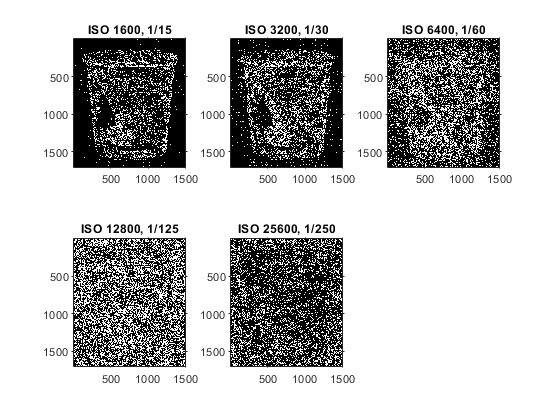

% show noise map
figure(1),
subplot(2,3,1), imshow(noise_1600,[]), title('ISO 1600, 1/15');
subplot(2,3,2), imshow(noise_3200,[]), title('ISO 3200, 1/30');
subplot(2,3,3), imshow(noise_6400,[]), title('ISO 6400, 1/60');
subplot(2,3,4), imshow(noise_12800,[]), title('ISO 12800, 1/125');
subplot(2,3,5), imshow(noise_25600,[]), title('ISO 25600, 1/250');

**Mean Filtering**

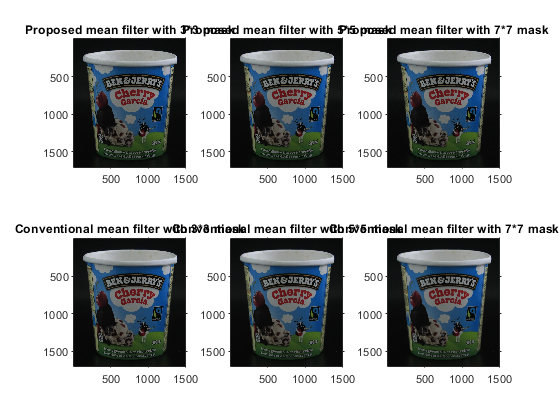

% ISO 1600
pmean_3_1600=project_mean(img1, noise_1600, 3);
pmean_5_1600=project_mean(img1, noise_1600, 5);
pmean_7_1600=project_mean(img1, noise_1600, 7);
mean_3_1600=mean_filt(img1, 3);
mean_5_1600=mean_filt(img1, 5);
mean_7_1600=mean_filt(img1, 7);
figure(2),
subplot(2,3,1), imshow(pmean_3_1600,[]), title('Proposed mean filter with 3*3 mask');
subplot(2,3,2), imshow(pmean_5_1600,[]), title('Proposed mean filter with 5*5 mask');
subplot(2,3,3), imshow(pmean_7_1600,[]), title('Proposed mean filter with 7*7 mask');
subplot(2,3,4), imshow(mean_3_1600,[]), title('Conventional mean filter with 3*3 mask');
subplot(2,3,5), imshow(mean_5_1600,[]), title('Conventional mean filter with 5*5 mask');
subplot(2,3,6), imshow(mean_7_1600,[]), title('Conventional mean filter with 7*7 mask');

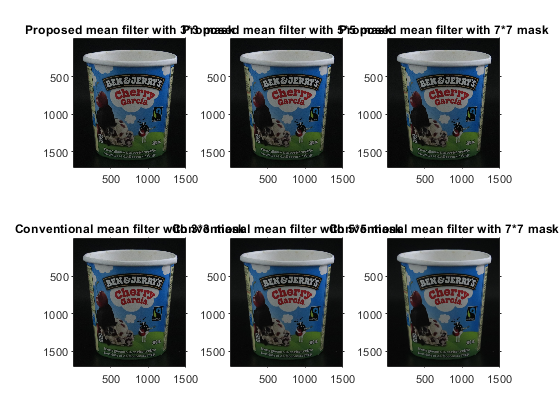


% ISO 3200
pmean_3_3200=project_mean(img2, noise_3200, 3);
pmean_5_3200=project_mean(img2, noise_3200, 5);
pmean_7_3200=project_mean(img2, noise_3200, 7);
mean_3_3200=mean_filt(img2, 3);
mean_5_3200=mean_filt(img2, 5);
mean_7_3200=mean_filt(img2, 7);
figure(3),
subplot(2,3,1), imshow(pmean_3_3200,[]), title('Proposed mean filter with 3*3 mask');
subplot(2,3,2), imshow(pmean_5_3200,[]), title('Proposed mean filter with 5*5 mask');
subplot(2,3,3), imshow(pmean_7_3200,[]), title('Proposed mean filter with 7*7 mask');
subplot(2,3,4), imshow(mean_3_3200,[]), title('Conventional mean filter with 3*3 mask');
subplot(2,3,5), imshow(mean_5_3200,[]), title('Conventional mean filter with 5*5 mask');
subplot(2,3,6), imshow(mean_7_3200,[]), title('Conventional mean filter with 7*7 mask');

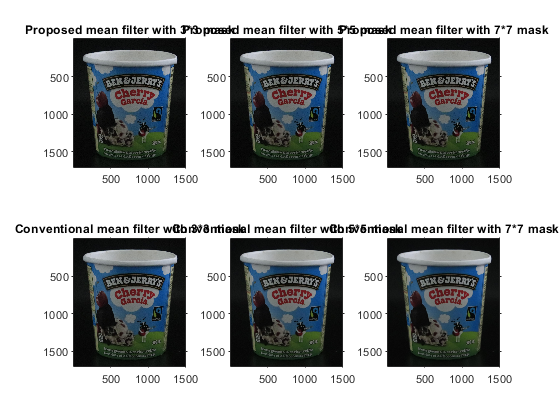


% ISO 6400
pmean_3_6400=project_mean(img3, noise_6400, 3);
pmean_5_6400=project_mean(img3, noise_6400, 5);
pmean_7_6400=project_mean(img3, noise_6400, 7);
mean_3_6400=mean_filt(img3, 3);
mean_5_6400=mean_filt(img3, 5);
mean_7_6400=mean_filt(img3, 7);
figure(4),
subplot(2,3,1), imshow(pmean_3_6400,[]), title('Proposed mean filter with 3*3 mask');
subplot(2,3,2), imshow(pmean_5_6400,[]), title('Proposed mean filter with 5*5 mask');
subplot(2,3,3), imshow(pmean_7_6400,[]), title('Proposed mean filter with 7*7 mask');
subplot(2,3,4), imshow(mean_3_6400,[]), title('Conventional mean filter with 3*3 mask');
subplot(2,3,5), imshow(mean_5_6400,[]), title('Conventional mean filter with 5*5 mask');
subplot(2,3,6), imshow(mean_7_6400,[]), title('Conventional mean filter with 7*7 mask');

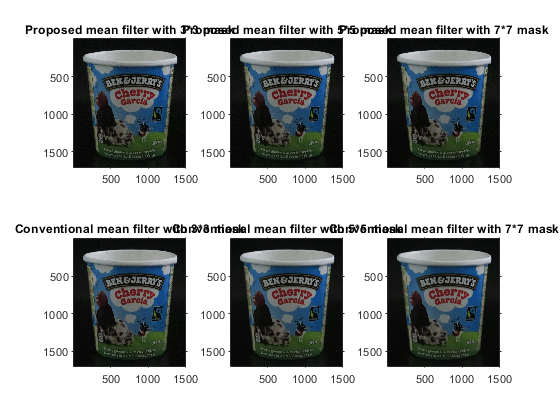


% ISO 12800
pmean_3_12800=project_mean(img4, noise_12800, 3);
pmean_5_12800=project_mean(img4, noise_12800, 5);
pmean_7_12800=project_mean(img4, noise_12800, 7);
mean_3_12800=mean_filt(img4, 3);
mean_5_12800=mean_filt(img4, 5);
mean_7_12800=mean_filt(img4, 7);
figure(5),
subplot(2,3,1), imshow(pmean_3_12800,[]), title('Proposed mean filter with 3*3 mask');
subplot(2,3,2), imshow(pmean_5_12800,[]), title('Proposed mean filter with 5*5 mask');
subplot(2,3,3), imshow(pmean_7_12800,[]), title('Proposed mean filter with 7*7 mask');
subplot(2,3,4), imshow(mean_3_12800,[]), title('Conventional mean filter with 3*3 mask');
subplot(2,3,5), imshow(mean_5_12800,[]), title('Conventional mean filter with 5*5 mask');
subplot(2,3,6), imshow(mean_7_12800,[]), title('Conventional mean filter with 7*7 mask');

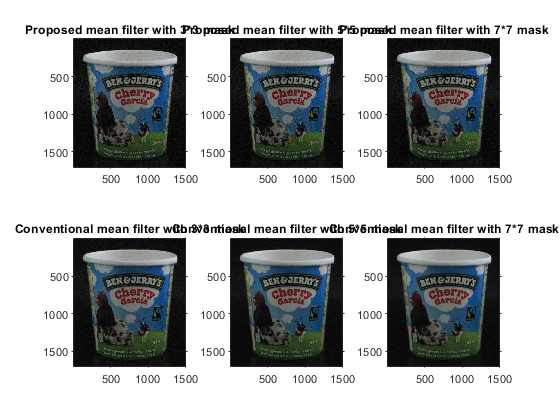


% ISO 25600
pmean_3_25600=project_mean(img5, noise_25600, 3);
pmean_5_25600=project_mean(img5, noise_25600, 5);
pmean_7_25600=project_mean(img5, noise_25600, 7);
mean_3_25600=mean_filt(img5, 3);
mean_5_25600=mean_filt(img5, 5);
mean_7_25600=mean_filt(img5, 7);
figure(6),
subplot(2,3,1), imshow(pmean_3_25600,[]), title('Proposed mean filter with 3*3 mask');
subplot(2,3,2), imshow(pmean_5_25600,[]), title('Proposed mean filter with 5*5 mask');
subplot(2,3,3), imshow(pmean_7_25600,[]), title('Proposed mean filter with 7*7 mask');
subplot(2,3,4), imshow(mean_3_25600,[]), title('Conventional mean filter with 3*3 mask');
subplot(2,3,5), imshow(mean_5_25600,[]), title('Conventional mean filter with 5*5 mask');
subplot(2,3,6), imshow(mean_7_25600,[]), title('Conventional mean filter with 7*7 mask');

**Median Filtering**

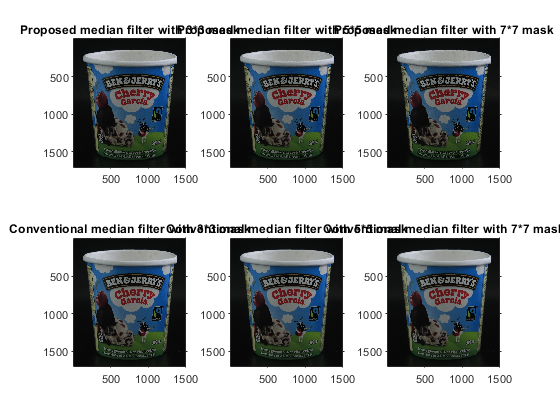

% ISO 1600
pmedian_3_1600=project_median(img1, noise_1600, 3);
pmedian_5_1600=project_median(img1, noise_1600, 5);
pmedian_7_1600=project_median(img1, noise_1600, 7);
median_3_1600(:,:,1)=medfilt2(img1(:,:,1), [3,3]);
median_3_1600(:,:,2)=medfilt2(img1(:,:,2), [3,3]);
median_3_1600(:,:,3)=medfilt2(img1(:,:,3), [3,3]);
median_5_1600(:,:,1)=medfilt2(img1(:,:,1), [5,5]);
median_5_1600(:,:,2)=medfilt2(img1(:,:,2), [5,5]);
median_5_1600(:,:,3)=medfilt2(img1(:,:,3), [5,5]);
median_7_1600(:,:,1)=medfilt2(img1(:,:,1), [7,7]);
median_7_1600(:,:,2)=medfilt2(img1(:,:,2), [7,7]);
median_7_1600(:,:,3)=medfilt2(img1(:,:,3), [7,7]);

figure(7),
subplot(2,3,1), imshow(pmedian_3_1600,[]), title('Proposed median filter with 3*3 mask');
subplot(2,3,2), imshow(pmedian_5_1600,[]), title('Proposed median filter with 5*5 mask');
subplot(2,3,3), imshow(pmedian_7_1600,[]), title('Proposed median filter with 7*7 mask');
subplot(2,3,4), imshow(median_3_1600,[]), title('Conventional median filter with 3*3 mask');
subplot(2,3,5), imshow(median_5_1600,[]), title('Conventional median filter with 5*5 mask');
subplot(2,3,6), imshow(median_7_1600,[]), title('Conventional median filter with 7*7 mask');

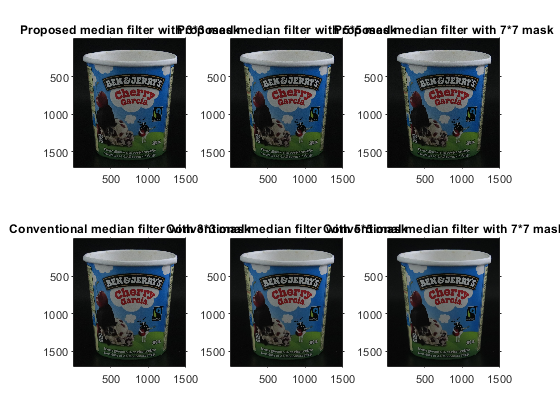


% ISO 3200
pmedian_3_3200=project_median(img2, noise_3200, 3);
pmedian_5_3200=project_median(img2, noise_3200, 5);
pmedian_7_3200=project_median(img2, noise_3200, 7);
median_3_3200(:,:,1)=medfilt2(img2(:,:,1), [3,3]);
median_3_3200(:,:,2)=medfilt2(img2(:,:,2), [3,3]);
median_3_3200(:,:,3)=medfilt2(img2(:,:,3), [3,3]);
median_5_3200(:,:,1)=medfilt2(img2(:,:,1), [5,5]);
median_5_3200(:,:,2)=medfilt2(img2(:,:,2), [5,5]);
median_5_3200(:,:,3)=medfilt2(img2(:,:,3), [5,5]);
median_7_3200(:,:,1)=medfilt2(img2(:,:,1), [7,7]);
median_7_3200(:,:,2)=medfilt2(img2(:,:,2), [7,7]);
median_7_3200(:,:,3)=medfilt2(img2(:,:,3), [7,7]);

figure(8),
subplot(2,3,1), imshow(pmedian_3_3200,[]), title('Proposed median filter with 3*3 mask');
subplot(2,3,2), imshow(pmedian_5_3200,[]), title('Proposed median filter with 5*5 mask');
subplot(2,3,3), imshow(pmedian_7_3200,[]), title('Proposed median filter with 7*7 mask');
subplot(2,3,4), imshow(median_3_3200,[]), title('Conventional median filter with 3*3 mask');
subplot(2,3,5), imshow(median_5_3200,[]), title('Conventional median filter with 5*5 mask');
subplot(2,3,6), imshow(median_7_3200,[]), title('Conventional median filter with 7*7 mask');

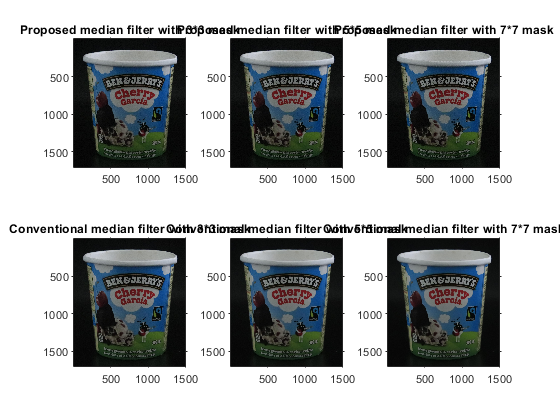


% ISO 6400
pmedian_3_6400=project_median(img3, noise_6400, 3);
pmedian_5_6400=project_median(img3, noise_6400, 5);
pmedian_7_6400=project_median(img3, noise_6400, 7);
median_3_6400(:,:,1)=medfilt2(img3(:,:,1), [3,3]);
median_3_6400(:,:,2)=medfilt2(img3(:,:,2), [3,3]);
median_3_6400(:,:,3)=medfilt2(img3(:,:,3), [3,3]);
median_5_6400(:,:,1)=medfilt2(img3(:,:,1), [5,5]);
median_5_6400(:,:,2)=medfilt2(img3(:,:,2), [5,5]);
median_5_6400(:,:,3)=medfilt2(img3(:,:,3), [5,5]);
median_7_6400(:,:,1)=medfilt2(img3(:,:,1), [7,7]);
median_7_6400(:,:,2)=medfilt2(img3(:,:,2), [7,7]);
median_7_6400(:,:,3)=medfilt2(img3(:,:,3), [7,7]);

figure(9),
subplot(2,3,1), imshow(pmedian_3_6400,[]), title('Proposed median filter with 3*3 mask');
subplot(2,3,2), imshow(pmedian_5_6400,[]), title('Proposed median filter with 5*5 mask');
subplot(2,3,3), imshow(pmedian_7_6400,[]), title('Proposed median filter with 7*7 mask');
subplot(2,3,4), imshow(median_3_6400,[]), title('Conventional median filter with 3*3 mask');
subplot(2,3,5), imshow(median_5_6400,[]), title('Conventional median filter with 5*5 mask');
subplot(2,3,6), imshow(median_7_6400,[]), title('Conventional median filter with 7*7 mask');

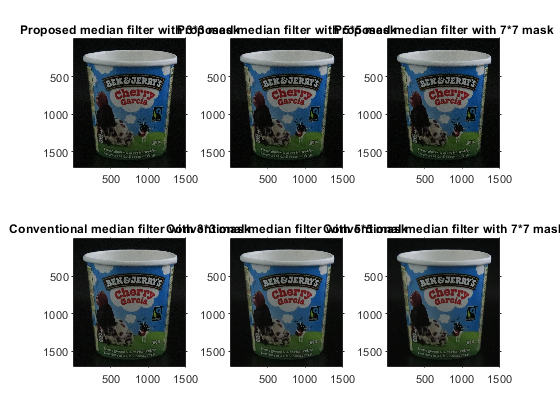


% ISO 12800
pmedian_3_12800=project_median(img4, noise_12800, 3);
pmedian_5_12800=project_median(img4, noise_12800, 5);
pmedian_7_12800=project_median(img4, noise_12800, 7);
median_3_12800(:,:,1)=medfilt2(img4(:,:,1), [3,3]);
median_3_12800(:,:,2)=medfilt2(img4(:,:,2), [3,3]);
median_3_12800(:,:,3)=medfilt2(img4(:,:,3), [3,3]);
median_5_12800(:,:,1)=medfilt2(img4(:,:,1), [5,5]);
median_5_12800(:,:,2)=medfilt2(img4(:,:,2), [5,5]);
median_5_12800(:,:,3)=medfilt2(img4(:,:,3), [5,5]);
median_7_12800(:,:,1)=medfilt2(img4(:,:,1), [7,7]);
median_7_12800(:,:,2)=medfilt2(img4(:,:,2), [7,7]);
median_7_12800(:,:,3)=medfilt2(img4(:,:,3), [7,7]);

figure(10),
subplot(2,3,1), imshow(pmedian_3_12800,[]), title('Proposed median filter with 3*3 mask');
subplot(2,3,2), imshow(pmedian_5_12800,[]), title('Proposed median filter with 5*5 mask');
subplot(2,3,3), imshow(pmedian_7_12800,[]), title('Proposed median filter with 7*7 mask');
subplot(2,3,4), imshow(median_3_12800,[]), title('Conventional median filter with 3*3 mask');
subplot(2,3,5), imshow(median_5_12800,[]), title('Conventional median filter with 5*5 mask');
subplot(2,3,6), imshow(median_7_12800,[]), title('Conventional median filter with 7*7 mask');

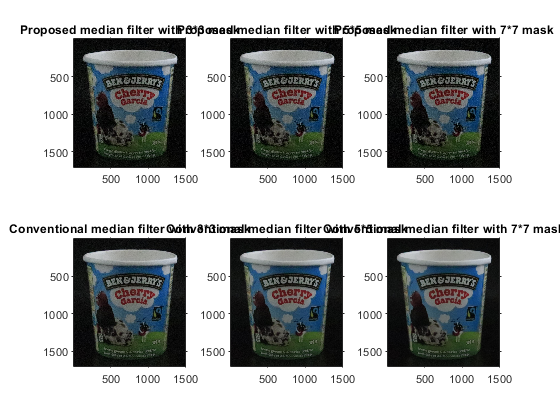


% ISO 25600
pmedian_3_25600=project_median(img5, noise_25600, 3);
pmedian_5_25600=project_median(img5, noise_25600, 5);
pmedian_7_25600=project_median(img5, noise_25600, 7);
median_3_25600(:,:,1)=medfilt2(img5(:,:,1), [3,3]);
median_3_25600(:,:,2)=medfilt2(img5(:,:,2), [3,3]);
median_3_25600(:,:,3)=medfilt2(img5(:,:,3), [3,3]);
median_5_25600(:,:,1)=medfilt2(img5(:,:,1), [5,5]);
median_5_25600(:,:,2)=medfilt2(img5(:,:,2), [5,5]);
median_5_25600(:,:,3)=medfilt2(img5(:,:,3), [5,5]);
median_7_25600(:,:,1)=medfilt2(img5(:,:,1), [7,7]);
median_7_25600(:,:,2)=medfilt2(img5(:,:,2), [7,7]);
median_7_25600(:,:,3)=medfilt2(img5(:,:,3), [7,7]);

figure(11),
subplot(2,3,1), imshow(pmedian_3_25600,[]), title('Proposed median filter with 3*3 mask');
subplot(2,3,2), imshow(pmedian_5_25600,[]), title('Proposed median filter with 5*5 mask');
subplot(2,3,3), imshow(pmedian_7_25600,[]), title('Proposed median filter with 7*7 mask');
subplot(2,3,4), imshow(median_3_25600,[]), title('Conventional median filter with 3*3 mask');
subplot(2,3,5), imshow(median_5_25600,[]), title('Conventional median filter with 5*5 mask');
subplot(2,3,6), imshow(median_7_25600,[]), title('Conventional median filter with 7*7 mask');

% write images
imwrite(pmean_3_1600, 'pmean_3_1600.jpg');
imwrite(pmean_5_1600, 'pmean_5_1600.jpg');
imwrite(pmean_7_1600, 'pmean_7_1600.jpg');
imwrite(mean_3_1600, 'mean_3_1600.jpg');
imwrite(mean_5_1600, 'mean_5_1600.jpg');
imwrite(mean_7_1600, 'mean_7_1600.jpg');
imwrite(pmean_3_3200, 'pmean_3_3200.jpg');
imwrite(pmean_5_3200, 'pmean_5_3200.jpg');
imwrite(pmean_7_3200, 'pmean_7_3200.jpg');
imwrite(mean_3_3200, 'mean_3_3200.jpg');
imwrite(mean_5_3200, 'mean_5_3200.jpg');
imwrite(mean_7_3200, 'mean_7_3200.jpg');
imwrite(pmean_3_6400, 'pmean_3_6400.jpg');
imwrite(pmean_5_6400, 'pmean_5_6400.jpg');
imwrite(pmean_7_6400, 'pmean_7_6400.jpg');
imwrite(mean_3_6400, 'mean_3_6400.jpg');
imwrite(mean_5_6400, 'mean_5_6400.jpg');
imwrite(mean_7_6400, 'mean_7_6400.jpg');
imwrite(pmean_3_12800, 'pmean_3_12800.jpg');
imwrite(pmean_5_12800, 'pmean_5_12800.jpg');
imwrite(pmean_7_12800, 'pmean_7_12800.jpg');
imwrite(mean_3_12800, 'mean_3_12800.jpg');
imwrite(mean_5_12800, 'mean_5_12800.jpg');
imwrite(mean_7_12800, 'mean_7_12800.jpg');
imwrite(pmean_3_25600, 'pmean_3_25600.jpg');
imwrite(pmean_5_25600, 'pmean_5_25600.jpg');
imwrite(pmean_7_25600, 'pmean_7_25600.jpg');
imwrite(mean_3_25600, 'mean_3_25600.jpg');
imwrite(mean_5_25600, 'mean_5_25600.jpg');
imwrite(mean_7_25600, 'mean_7_25600.jpg');
imwrite(pmedian_3_1600, 'pmedian_3_1600.jpg');
imwrite(pmedian_5_1600, 'pmedian_5_1600.jpg');
imwrite(pmedian_7_1600, 'pmedian_7_1600.jpg');
imwrite(median_3_1600, 'median_3_1600.jpg');
imwrite(median_5_1600, 'median_5_1600.jpg');
imwrite(median_7_1600, 'median_7_1600.jpg');
imwrite(pmedian_3_3200, 'pmedian_3_3200.jpg');
imwrite(pmedian_5_3200, 'pmedian_5_3200.jpg');
imwrite(pmedian_7_3200, 'pmedian_7_3200.jpg');
imwrite(median_3_3200, 'median_3_3200.jpg');
imwrite(median_5_3200, 'median_5_3200.jpg');
imwrite(median_7_3200, 'median_7_3200.jpg');
imwrite(pmedian_3_6400, 'pmedian_3_6400.jpg');
imwrite(pmedian_5_6400, 'pmedian_5_6400.jpg');
imwrite(pmedian_7_6400, 'pmedian_7_6400.jpg');
imwrite(median_3_6400, 'median_3_6400.jpg');
imwrite(median_5_6400, 'median_5_6400.jpg');
imwrite(median_7_6400, 'median_7_6400.jpg');
imwrite(pmedian_3_12800, 'pmedian_3_12800.jpg');
imwrite(pmedian_5_12800, 'pmedian_5_12800.jpg');
imwrite(pmedian_7_12800, 'pmedian_7_12800.jpg');
imwrite(median_3_12800, 'median_3_12800.jpg');
imwrite(median_5_12800, 'median_5_12800.jpg');
imwrite(median_7_12800, 'median_7_12800.jpg');
imwrite(pmedian_3_25600, 'pmedian_3_25600.jpg');
imwrite(pmedian_5_25600, 'pmedian_5_25600.jpg');
imwrite(pmedian_7_25600, 'pmedian_7_25600.jpg');
imwrite(median_3_25600, 'median_3_25600.jpg');
imwrite(median_5_25600, 'median_5_25600.jpg');
imwrite(median_7_25600, 'median_7_25600.jpg');

imwrite(noise_1600, 'noise_1600.jpg');
imwrite(noise_3200, 'noise_3200.jpg');
imwrite(noise_6400, 'noise_6400.jpg');
imwrite(noise_12800, 'noise_12800.jpg');
imwrite(noise_25600, 'noise_25600.jpg');

pmean_err1600_3=immse(pmean_3_1600, img)

pmean_err1600_3 = 18.4677

pmean_err1600_5=immse(pmean_5_1600, img)

pmean_err1600_5 = 22.9279

pmean_err1600_7=immse(pmean_7_1600, img)

pmean_err1600_7 = 29.4269

mean_err1600_3=immse(mean_3_1600, img)

mean_err1600_3 = 22.6416

mean_err1600_5=immse(mean_5_1600, img)

mean_err1600_5 = 41.5711

mean_err1600_7=immse(mean_7_1600, img)

mean_err1600_7 = 65.3337


pmean_err3200_3=immse(pmean_3_3200, img)

pmean_err3200_3 = 29.2054

pmean_err3200_5=immse(pmean_5_3200, img)

pmean_err3200_5 = 32.4611

pmean_err3200_7=immse(pmean_7_3200, img)

pmean_err3200_7 = 37.6802

mean_err3200_3=immse(mean_3_3200, img)

mean_err3200_3 = 33.8192

mean_err3200_5=immse(mean_5_3200, img)

mean_err3200_5 = 50.3157

mean_err3200_7=immse(mean_7_3200, img)

mean_err3200_7 = 71.4814


pmean_err6400_3=immse(pmean_3_6400, img)

pmean_err6400_3 = 46.5231

pmean_err6400_5=immse(pmean_5_6400, img)

pmean_err6400_5 = 48.7638

pmean_err6400_7=immse(pmean_7_6400, img)

pmean_err6400_7 = 53.1870

mean_err6400_3=immse(mean_3_6400, img)

mean_err6400_3 = 48.3475

mean_err6400_5=immse(mean_5_6400, img)

mean_err6400_5 = 61.7648

mean_err6400_7=immse(mean_7_6400, img)

mean_err6400_7 = 80.7639


pmean_err12800_3=immse(pmean_3_12800, img)

pmean_err12800_3 = 73.6098

pmean_err12800_5=immse(pmean_5_12800, img)

pmean_err12800_5 = 75.6781

pmean_err12800_7=immse(pmean_7_12800, img)

pmean_err12800_7 = 80.0331

mean_err12800_3=immse(mean_3_12800, img)

mean_err12800_3 = 72.8085

mean_err12800_5=immse(mean_5_12800, img)

mean_err12800_5 = 82.7112

mean_err12800_7=immse(mean_7_12800, img)

mean_err12800_7 = 98.4736


pmean_err25600_3=immse(pmean_3_25600, img)

pmean_err25600_3 = 142.0263

pmean_err25600_5=immse(pmean_5_25600, img)

pmean_err25600_5 = 140.5742

pmean_err25600_7=immse(pmean_7_25600, img)

pmean_err25600_7 = 141.7886

mean_err25600_3=immse(mean_3_25600, img)

mean_err25600_3 = 118.9356

mean_err25600_5=immse(mean_5_25600, img)

mean_err25600_5 = 118.8368

mean_err25600_7=immse(mean_7_25600, img)

mean_err25600_7 = 129.4546


pmedian_err1600_3=immse(pmedian_3_1600, img)

pmedian_err1600_3 = 30.4686

pmedian_err1600_5=immse(pmedian_5_1600, img)

pmedian_err1600_5 = 63.9139

pmedian_err1600_7=immse(pmedian_7_1600, img)

pmedian_err1600_7 = 115.3097

median_err1600_3=immse(median_3_1600, img)

median_err1600_3 = 18.5777

median_err1600_5=immse(median_5_1600, img)

median_err1600_5 = 26.5068

median_err1600_7=immse(median_7_1600, img)

median_err1600_7 = 39.5153


pmedian_err3200_3=immse(pmedian_3_3200, img)

pmedian_err3200_3 = 37.7475

pmedian_err3200_5=immse(pmedian_5_3200, img)

pmedian_err3200_5 = 61.4752

pmedian_err3200_7=immse(pmedian_7_3200, img)

pmedian_err3200_7 = 102.2300

median_err3200_3=immse(median_3_3200, img)

median_err3200_3 = 29.5956

median_err3200_5=immse(median_5_3200, img)

median_err3200_5 = 36.2224

median_err3200_7=immse(median_7_3200, img)

median_err3200_7 = 47.3877


pmedian_err6400_3=immse(pmedian_3_6400, img)

pmedian_err6400_3 = 57.4243

pmedian_err6400_5=immse(pmedian_5_6400, img)

pmedian_err6400_5 = 79.1024

pmedian_err6400_7=immse(pmedian_7_6400, img)

pmedian_err6400_7 = 113.6562

median_err6400_3=immse(median_3_6400, img)

median_err6400_3 = 45.3447

median_err6400_5=immse(median_5_6400, img)

median_err6400_5 = 49.7309

median_err6400_7=immse(median_7_6400, img)

median_err6400_7 = 59.1377


pmedian_err12800_3=immse(pmedian_3_12800, img)

pmedian_err12800_3 = 89.4764

pmedian_err12800_5=immse(pmedian_5_12800, img)

pmedian_err12800_5 = 111.5861

pmedian_err12800_7=immse(pmedian_7_12800, img)

pmedian_err12800_7 = 142.3094

median_err12800_3=immse(median_3_12800, img)

median_err12800_3 = 70.6604

median_err12800_5=immse(median_5_12800, img)

median_err12800_5 = 72.4604

median_err12800_7=immse(median_7_12800, img)

median_err12800_7 = 79.3640


pmedian_err25600_3=immse(pmedian_3_25600, img)

pmedian_err25600_3 = 157.5393

pmedian_err25600_5=immse(pmedian_5_25600, img)

pmedian_err25600_5 = 175.5299

pmedian_err25600_7=immse(pmedian_7_25600, img)

pmedian_err25600_7 = 191.9823

median_err25600_3=immse(median_3_25600, img)

median_err25600_3 = 121.2953

median_err25600_5=immse(median_5_25600, img)

median_err25600_5 = 114.1085

median_err25600_7=immse(median_7_25600, img)

median_err25600_7 = 117.4777